% Daten einlesen und in Variablen aufteilen
[spec, firstWordsList, wavelengths] = NIR_vorbereiten('G:\Meine Ablage\Master\02_research\Masterarbeit\04_Daten\Trainingsdatensatz');

% Initialisierung Array fuer Indizes
idxArray = zeros(size(firstWordsList));
% Setzen der Indizes pro Material
idxArray(strcmp(firstWordsList, 'HDPE')) = 1;
idxArray(strcmp(firstWordsList, 'LDPE')) = 2;
idxArray(strcmp(firstWordsList, 'PET')) = 3;
idxArray(strcmp(firstWordsList, 'PP')) = 4;
idxArray(strcmp(firstWordsList, 'PS')) = 5;
% Spektrum und Indexarray definieren
allSpectra2D = spec';
indexArray = idxArray';

% Zentrale Wellenlaengen der Filter
filter_wl = [1015, 1145, 1190, 1215, 1395, 1542, 1647];
% Standardmaessige Initialisierung der Halbwertsbreiten
fwhm_values = ones(size(filter_wl)) * 10;
%Fuer benutzerdefinierte fwhm
%fwhm_values = [10,10,12,12];

% Bereiche der Filter initiieren
filter_regions = zeros(length(filter_wl), 2);

for i = 1:length(filter_wl)
    fwhm = fwhm_values(i); % Abrufen der entsprechenden Halbwertsbreite für den aktuellen Filter
    hbf = fwhm / 2;
    filter_regions(i,1) = filter_wl(i) -hbf;
    filter_regions(i,2) = filter_wl(i) +hbf;
end

integral_values = zeros(size(allSpectra2D,1), length(filter_regions));
ymin = inf;
ymax = -inf;

% Iteriere durch alle Spektren
for i = 1:size(allSpectra2D,1)
    df = allSpectra2D(i,:);
    ymin = min(ymin, min(df));
    ymax = max(ymax, max(df));

    % Funktion erstellen durch Interpolation
    interp_function = @(x) interp1(wavelengths, df, x, 'linear', 'extrap');
    % Berechnung des Integrals fuer jeden Bereich
    for j = 1:length(filter_regions)
        fun = interp_function;
        integral_values(i,j) = integral(fun, filter_regions(j,1), filter_regions(j,2));
    end
end

disp('Integralwerte für jeden Bereich:');

Integralwerte für jeden Bereich:


disp(integral_values);

    4.9043    5.1663    4.2831    3.1737    4.0712    5.1825    5.4450
    4.9166    5.1984    4.3240    3.2032    4.1240    5.2549    5.5221
    4.8495    5.1068    4.2424    3.1452    4.0285    5.1237    5.3766
    4.7986    5.0517    4.1888    3.1016    3.9707    5.0542    5.3040
    3.7897    4.1313    3.1775    2.0527    2.9923    4.2140    4.5294
    3.8335    4.1807    3.2790    2.1746    3.1192    4.3282    4.6425
    7.0521    6.8122    5.1615    3.7863    4.1815    5.2158    5.3050
    7.5627    7.3157    5.5624    4.1215    4.5307    5.6371    5.7480
    7.0149    6.7811    5.1466    3.7797    4.1721    5.2013    5.2930
    7.5930    7.3487    5.5849    4.1391    4.5488    5.6618    5.7742
    5.3795    5.1356    3.8542    2.6303    2.8920    3.4838    3.3703
    5.5089    5.2714    3.9967    2.7705    3.0210    3.6209    3.5046
    4.9136    4.5258    3.0595    1.9297    1.8438    2.1657    2.1225
    4.0542    3.7117    2.2261    1.7752    1.6375    2.2072    2.0058
    4.

latent =     2.5387
    0.6205
    0.2634
    0.1808
    0.0237
    0.0022
    0.0000


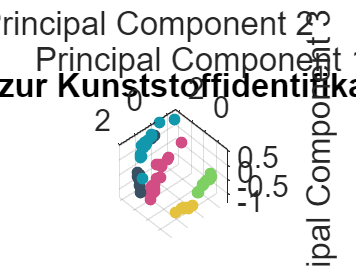

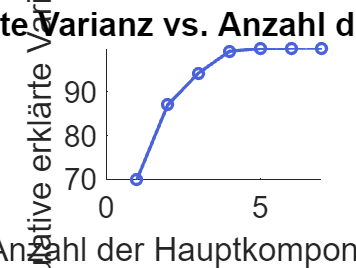

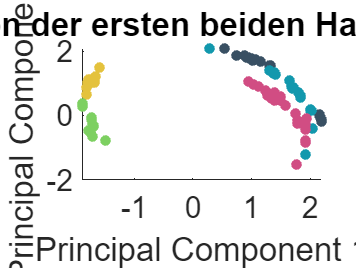


% Durchfuehrung der PCA
[coeff, X_pca, y] = pca_analysis(integral_values, indexArray);